clear
close all
clc 

## you will need to change:

% the file to load
% landing nb os size
%format_spec='Trace_4_%d_%d_%d';
% a (approach potential value) and b (ocp curve limit potential value)
% OCP maps upper and lower limit 

## Experiment Details of the Spatial Map

droplet_size=60;

file=('20230721 CA6NM SS, Eapp -1V, 1000 ppm NaCl.mat');
S=load(file);
num_landings_y = 21 %Size of grid in y axis

num_landings_y = 21

num_landings_x = 31 %Size of grid in x axis

num_landings_x = 31

landing_separation_y=5; %Separation between landing points in y
landing_separation_x=5; %Separation between landing points in x
Lx=num_landings_x*landing_separation_x; %Length of x axis for map
Ly=num_landings_y*landing_separation_y; %Length of y axis for map

## create x,y coordinates

%B = repmat(A,n) returns an array containing n copies of A in the row and column dimensions
%x=repmat(0:5:5*(5-1),(21-1)
x=repmat(0:landing_separation_x:landing_separation_x*(num_landings_x-1),num_landings_y,1);
y=repmat(0:landing_separation_y:landing_separation_y*(num_landings_y-1),num_landings_x,1);
x=x';
x=x(:);
y=y(:);

## Defining the EC Measurement at Each Landing


Ecorr=zeros(num_landings_x*num_landings_y,1);
OCP=zeros(num_landings_x*num_landings_y,1);
pit_curr=zeros(num_landings_x*num_landings_y,1);
pit_potential= zeros(num_landings_x*num_landings_y,1);
end_potential = zeros(num_landings_x*num_landings_y,1);
curr_E1 = zeros(num_landings_x*num_landings_y,1);

%total number of measurements (1 ocp and 1 pdp at each point)
num_pdp = 0;
pdp_curr = cell(num_landings_x*num_landings_y, 1);
pdp_potential = cell(num_landings_x*num_landings_y, 1);

for k=1:2*num_landings_x*num_landings_y

    format_spec='Trace_2_%d_%d_%d';
    
    [m,n]=size(S.(sprintf(format_spec,k,1,1))); 
    %using the formatting operators specified by formatSpec and returns the resulting text in str.
   
    currents=S.(sprintf(format_spec,k,1,1))(:,2);
    potentials=S.(sprintf(format_spec,k,1,2))(:,2);
     %even numbers of measurements are PDPs, odd numbers are the ocp
    %for PDPs: define Ecorr as: the potential at the minim value of I,
    % and define pit_curr as the final point of the pdp. 
    if mod(k,2)==0
        num_pdp = num_pdp + 1;
        yc=log10(abs(currents));
        [icorr,I]=min(yc);
        Ecorr(num_pdp)=S.(sprintf(format_spec,k,1,2))(I,2);
        pit_curr(num_pdp)=S.(sprintf(format_spec,k,1,1))(end,2)*1E9;
        pit_potential(num_pdp)=S.(sprintf(format_spec,k,1,1))(end,2)*1E9;
        pdp_curr{num_pdp} = currents;
        pdp_potential{num_pdp} = potentials;
        
        % define curr_E1 as the current at E1 potential
        target_potential = 0.5; % target potential in volts
        [~, index_E1] = min(abs(potentials - target_potential));
        curr_E1(num_pdp) = currents(index_E1) * 1E9;
                
    %for odd numbers, they are OCP
    % define E(OCP)as the final point recorded in the OCP run.
    else
        OCP((k+1)/2)=S.(sprintf(format_spec,k,1,2))(end,2);
    end
end



## setting the limits to which points to show in the  map (removing the false landing)

%Removing false landing for OCP and PDP curves:
a = -1.4; % set the lower limit for OCP
b = 0.5; % set the upper limit for OCP

%Removing false landing for the maps
% define OCP limit
OCP_limit = [a, b];

% remove outliers
OCP(OCP < OCP_limit(1) | OCP > OCP_limit(2)) = NaN;
Ecorr(OCP < OCP_limit(1) | OCP >OCP_limit(2) | isnan(OCP)) = NaN;
pit_curr(OCP < OCP_limit(1) | OCP >OCP_limit(2) | isnan(OCP)) = NaN;
end_potential(OCP < OCP_limit(1) | OCP >OCP_limit(2) | isnan(OCP)) = NaN;
curr_E1(OCP < OCP_limit(1) | OCP >OCP_limit(2) | isnan(OCP)) = NaN;


c = -1

c = -1 V


## OCP map [Last OCP Recorded]

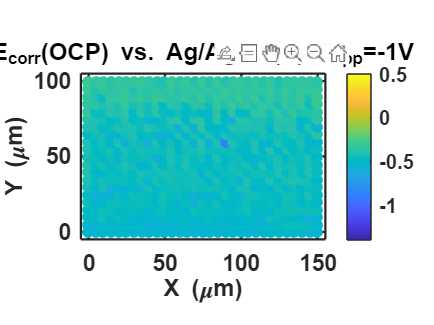

%% OCP MAP 

f1=figure;
scatter(x,y,droplet_size,OCP,'filled');
clim([a b]); % set color axis limits
box on
axis([-landing_separation_y Lx -landing_separation_x Ly])
pbaspect([num_landings_x num_landings_y 1])
h1=colorbar('eastoutside');
set(gca,'FontSize',15,'LineWidth',1.5,'FontWeight','bold')
ttl = sprintf('E_{corr}(OCP) vs. Ag/AgCl (V) E_{app}=%.0fV', c);
%title(ttl,'FontWeight','bold', 'FontSize',16);

xlabel('X (\mum)','FontSize',16)
ylabel('Y (\mum)','FontSize',16)

%xlim([-50 650])
%ylim([-50 350])
%axis equal

## **Ecorr map [Potential at Imin in PDP]**

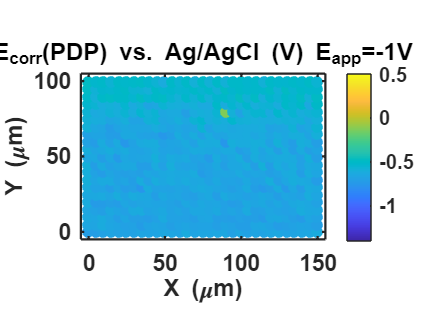


%%Ecorr Map

f2=figure;
scatter(x,y,droplet_size,Ecorr,'filled');
caxis([a b]); % set color axis limits
box on
axis([-landing_separation_y Lx -landing_separation_x Ly])
pbaspect([num_landings_x num_landings_y 1])
set(gca,'layer','top')

h2=colorbar('eastoutside');
set(gca,'FontSize',15,'LineWidth',1.5,'FontWeight','bold');
ttl = sprintf('E_{corr}(PDP) vs. Ag/AgCl (V) E_{app}=%.0fV', c);
title(ttl,'FontWeight','bold', 'FontSize',16);

xlabel('X (\mum)','FontSize',16)
ylabel('Y (\mum)','FontSize',16)

## Histogram of OCP distirbution

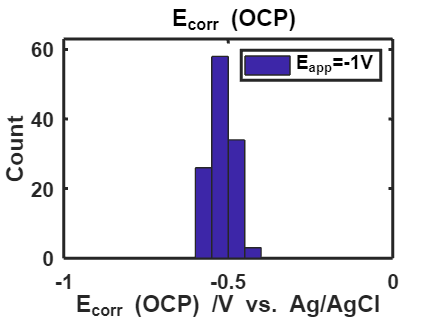

% Take the first 495 values
OCP1 = OCP(1:121);

% Define the bin edges with 0.05 V spacing
edges = -1.0:0.05:-0.15;

% Compute the histogram counts
counts_OCP = histcounts(OCP1, edges);

% Plot the histogram
f4=figure;
bar(edges(1:end-1), counts_OCP, 'histc');
xlabel('E_{corr} (OCP) /V vs. Ag/AgCl');
ylabel('Count');
title(' E_{corr} (OCP)')

set(gca,'FontSize',14,'linewidth',2.0,'Fontweight','bold');
legend(sprintf('E_{app}=%.0fV', c), 'Location','northeast');
%xlim([-0.8 -0.15])
ylim([0 max(counts_OCP)+5]);

## Histogram of Ecorr (PDP) distirbution

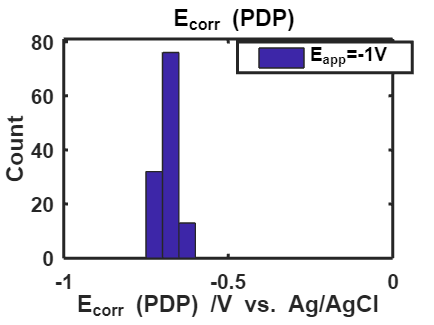

% Take the first 495 values
Ecorr1 = Ecorr(1:121);

% Define the bin edges with 0.05 V spacing
edges = -1.0:0.05:-0.15;

% Compute the histogram counts
counts_Ecorr = histcounts(Ecorr1, edges);

% Plot the histogram
f3=figure;
bar(edges(1:end-1), counts_Ecorr, 'histc');
xlabel('E_{corr} (PDP) /V vs. Ag/AgCl');
ylabel('Count');
title(' E_{corr} (PDP)')

set(gca,'FontSize',14,'linewidth',2.0,'Fontweight','bold');
legend(sprintf('E_{app}=%.0fV', c), 'Location','northeast');
%xlim([-0.8 -0.15])
ylim([0 max(counts_Ecorr)+5]);

legend("Position", [0.61,0.79047,0.27767,0.064767])

## Combined Histogram of OCP and Ecorr 

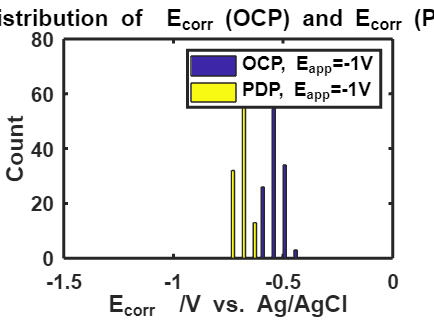

% Plot the histograms
f12 = figure;
bar(edges(1:end-1), [counts_OCP; counts_Ecorr]', 'histc');
xlabel('E_{corr}  /V vs. Ag/AgCl');
ylabel('Count');
title('Distribution of  E_{corr} (OCP) and E_{corr} (PDP)');

set(gca,'FontSize',14,'linewidth',2.0,'Fontweight','bold');
legend({sprintf('OCP, E_{app}=%.0fV', c), sprintf('PDP, E_{app}=%.0fV', c)}, 'Location','northeast');
xlim([-1.5 0])

## Pitting map [Last current in PDP]

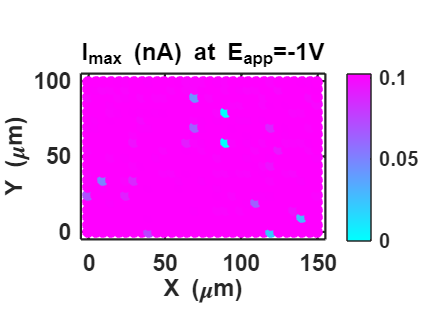

f5=figure;

scatter(x,y,droplet_size,pit_curr,'filled');

box on
axis([-landing_separation_y Lx  -landing_separation_x Ly])
pbaspect([num_landings_x num_landings_y 1])
colormap cool;
% set(gca,'layer','top')
% shading flat; grid off;
h=colorbar('eastoutside');

% h.Limits = [30 120];

set(gca,'FontSize',15,'LineWidth',1.5,'FontWeight','bold');
ttl = sprintf('I_{max} (nA) at E_{app}=%.0fV', c);
title(ttl,'FontWeight','bold', 'FontSize',16);
%ylabel(h,'Current at E=0V (pA)','FontSize',15);
xlabel('X (\mum)','FontSize',16)
ylabel('Y (\mum)','FontSize',16)

## Current at E = 0.5 V Map

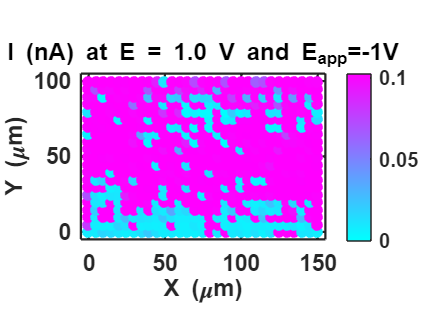

f6 = figure;

scatter(x,y,droplet_size,curr_E1,'filled');

box on
axis([-landing_separation_y Lx  -landing_separation_x Ly])
pbaspect([num_landings_x num_landings_y 1])
colormap cool;
% set(gca,'layer','top')
% shading flat; grid off;
h=colorbar('eastoutside');

% h.Limits = [30 120];

set(gca,'FontSize',15,'LineWidth',1.5,'FontWeight','bold');
ttl = sprintf('I (nA) at E = 1.0 V and E_{app}=%.0fV', c);
title(ttl,'FontWeight','bold', 'FontSize',16);
%ylabel(h,'Current at E=0V (pA)','FontSize',15);
xlabel('X (\mum)','FontSize',16)
ylabel('Y (\mum)','FontSize',16)

## Compare OCP and Ecorr in Curve

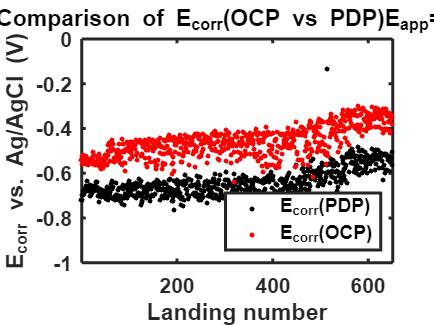

f7=figure;
plot1=plot(Ecorr,'.');
set(plot1,'color','k','Markersize',10);
hold on
plot2=plot(OCP,'.');
set(plot2,'color','r','Markersize',10);

legend('E_{corr}(PDP)','E_{corr}(OCP)');
ttl = sprintf('Comparison of E_{corr}(OCP vs PDP)E_{app}=%.0fV', c);
title(ttl,'FontWeight','bold', 'FontSize',16);
xlabel('Landing number')
ylabel('E_{corr} vs. Ag/AgCl (V)');
xlim([1 num_landings_x*num_landings_y])
ylim([-1 -0]);
set(gca,'FontSize',14,'linewidth',2.0,'Fontweight','bold')
legend('Location','southeast')

## End Potential: where Current =100 pA is reached in PDP for the first time

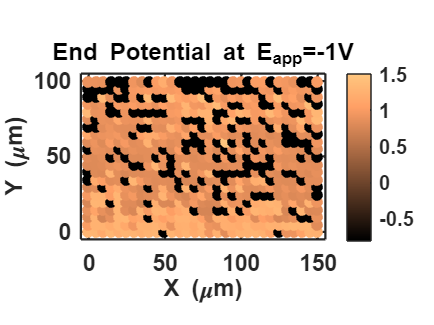

f8 = figure;

% initialize arrays
I_max = zeros(num_pdp, 1);
end_potential = zeros(num_pdp, 1);

% loop through each PDP
for k = 1:num_pdp
    % get the current and potential arrays for this PDP
    I = abs(pdp_curr{k});
    V = pdp_potential{k};
    
    % find the difference between each pair of adjacent current values
    I_diff = diff(I);
    
    % find the indices where the difference is zero
    idx = find(I_diff == 0);
    
    % remove current2 if current2 - current1 = 0
    if ~isempty(idx)
        I(idx+1) = [];
        V(idx+1) = [];
    end
    
    % find I_max of the remaining current values
    I_max(k) = max(I);
    
    % find the potential value corresponding to I_max
    end_potential(k) = V(find(I == I_max(k), 1));
end


%limit for the end potential to remove outliers
end_potential(OCP < OCP_limit(1) | OCP >OCP_limit(2) | isnan(OCP)) = NaN;


% Draw scatter plot of end_potential array
f5 = figure;
scatter(x,y,droplet_size,end_potential,'filled');
box on
axis([-landing_separation_y Lx  -landing_separation_x Ly])
pbaspect([num_landings_x num_landings_y 1])
colormap copper;
box on

% set(gca,'layer','top')
% shading flat; grid off;
h=colorbar('eastoutside');

set(gca,'FontSize',15,'LineWidth',1.5,'FontWeight','bold');
ttl = sprintf('End Potential at E_{app}=%.0fV', c);
title(ttl,'FontWeight','bold', 'FontSize',16);
%ylabel(h,'Current at E=0V (pA)','FontSize',15);
xlabel('X (\mum)','FontSize',16)
ylabel('Y (\mum)','FontSize',16)
caxis([-0.8 1.5]); % set color axis limits

%xlim([-20 820])
%ylim([-200 600])

## Histogram of End potential

f9=figure

f9 =   Figure (33) with properties:

      Number: 33
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [360 178 560 420]
       Units: 'pixels'

  Show all properties


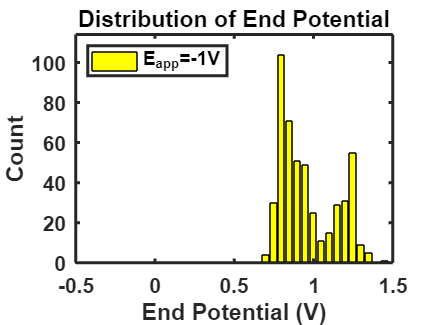

% Remove NaN values from the end_potential array
end_potential(isnan(end_potential)) = [];

% Define the bin edges with 0.05 V spacing
edges = -0.5:0.05:1.5;

% Compute the histogram counts
counts = histcounts(end_potential, edges);

% Plot the histogram
figure;
bar(edges(1:end-1), counts, 'FaceColor', 'yellow');

xlabel('End Potential (V)');
ylabel('Count');
ttl= sprintf('Distribution of End Potential');
title(ttl,'FontWeight','bold', 'FontSize',16)

% Adjust plot settings
set(gca, 'FontSize', 14, 'LineWidth', 2, 'FontWeight', 'bold');
xlim([-0.5 1.5]);
ylim([0 max(counts)+10]);

set(gca,'FontSize',14,'linewidth',2.0,'Fontweight','bold');
legend(sprintf('E_{app}=%.0fV', c), 'Location','northwest');

## OCP Curve

%Choose the points to be plotted in ocp and pdp plots
k_values = [61:70]

k_values =     61    62    63    64    65    66    67    68    69    70


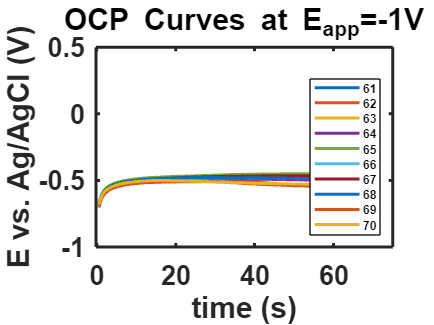


f10 = figure;

for k1 = k_values 
    to_plot = true; % flag to keep track of whether to plot or not
    for k=k1*2-1

        % extract OCP data
        ocp_potentials=S.(sprintf(format_spec,k,1,2))(:,2);
        ocp_times=S.(sprintf(format_spec,k,1,2))(:,1);

        % extract PDP data
        pdp_currents=S.(sprintf(format_spec,k+1,1,1))(:,2);
        pdp_potentials=S.(sprintf(format_spec,k+1,1,2))(:,2);
        pdp_times=S.(sprintf(format_spec,k+1,1,2))(:,1);

        % find the last potential in the OCP curve
        last_ocp_potential = ocp_potentials(end);

        % check if the last potential is within the desired range
        if last_ocp_potential < a || last_ocp_potential > b
             %if not, do not plot the OCP and PDP curves for this pair of k values
            to_plot = false;
        end

        if to_plot
            % plot OCP and PDP curves if to_plot is true
            legent = sprintf('%d',k1);
            plot(ocp_times, ocp_potentials, 'linewidth', 2, 'DisplayName', legent);
            hold on
            %plot(pdp_times, pdp_potentials, 'linewidth', 2, 'DisplayName', '');
            %hold on

                % mark the corresponding k value as plotted
            ocp_plotted(k1 == k_values) = true;
        end
    end
end

       
ttl = sprintf('OCP Curves at E_{app}=%.0fV', c);
title(ttl,'FontWeight','bold', 'FontSize',16);
xlabel('time (s)')
ylabel('E vs. Ag/AgCl (V)')
ylim([-1 0.5])
xlim([-0.20 75])
set(gca,'FontSize',18,'linewidth',2,'FontWeight','bold')

legend('FontSize',8,'LineWidth',0.5)
legend show;
legend location southeast;

## PDP Plots

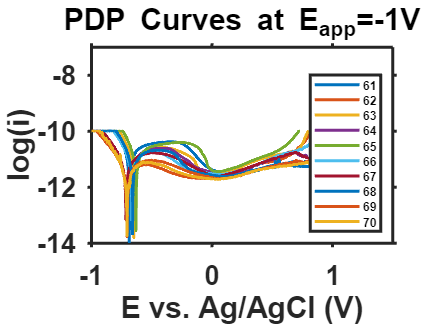

f12 = figure;

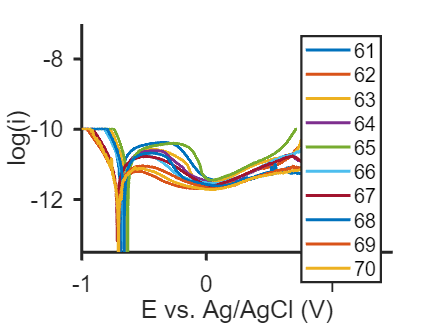

figure(f12);
hold on;

box on; % Add axis lines on all four sides

for k1 = k_values
    to_plot = true; % flag to keep track of whether to plot or not
    for k = k1*2
        currents = S.(sprintf(format_spec,k,1,1))(:,2);
        potentials = S.(sprintf(format_spec,k,1,2))(:,2);
        times = S.(sprintf(format_spec,k,1,2))(:,1);
        y1 = currents(:);
        ys1 = movmean(y1, 10);  % Smooth current by averaging points
        ys = log10(abs(ys1));
        x = potentials(:);
        
        % Check if the first y-value is less than -11
        if ys(1) < -11
            to_plot = false; % Set the flag to not plot the curve
            break; % Exit the loop
        end
        
        % Remove data points where ys < -12.5
        filtered_indices = ys >= -15;
        x_filtered = x(filtered_indices);
        ys_filtered = ys(filtered_indices);
        
        % Plot the filtered data points
        if ~isempty(x_filtered) && ~isempty(ys_filtered)
            legend_text = sprintf('%d', k1);
            plot(x_filtered, ys_filtered, 'linewidth', 2, 'DisplayName', legend_text);
        end
    end
    
    % Plotting additional curve-specific code here (if needed)
    
end

% Setting the limits of the graph:
xlabel('E vs. Ag/AgCl (V)', 'FontName', 'Arial', 'FontWeight', 'normal', 'FontSize', 14)
ylabel('log(i)', 'FontName', 'Arial', 'FontWeight', 'normal', 'FontSize', 14)
xlim([-1 1.5]) % Set x-axis range from -1 to 1
ylim([-13.5 -7])
%yticks(-13:1:-9.5) % Set y-axis ticks with 1 value increment
set(gca, 'FontName', 'Arial', 'FontSize', 15, 'LineWidth', 2)
box off
legend('FontSize', 13, 'LineWidth', 2, 'FontName', 'Arial', 'FontWeight','normal') % Set the legend font properties
legend('show')
legend('location', 'southeast')

% Move the axes ticks to the outside and make them longer
ax = gca;
ax.TickDir = 'out';
ax.TickLength = [0.02 0.02];

% Adjust the legend box position and properties
legend_box = legend;
set(legend_box, 'LineWidth', 1.5) % Increase the LineWidth to make the legend box thicker